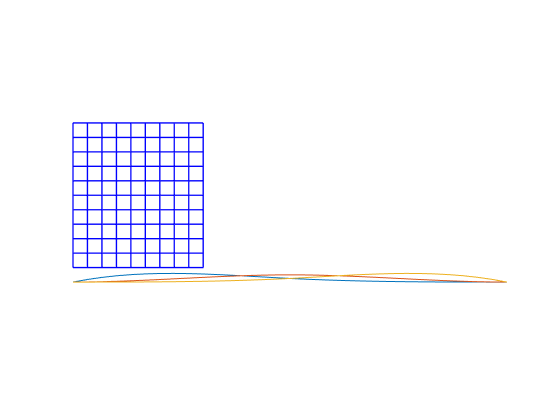

n = 10;
m = 11;
[x1, x2] = meshgrid(1:n, 1:m);
plotgrid(x1, x2);

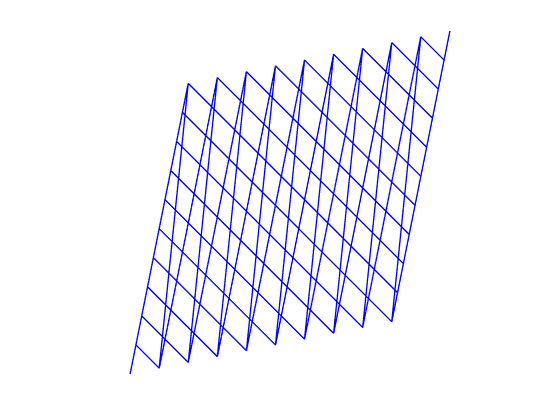

Q = [ones(size(x1(:))) x1(:) x2(:)];
w = [1 0 0.2 0 0.2 0]';
y = [x1(:); x2(:)] + kron(eye(2), Q) * w;
y1 = reshape(y(1:end/2), n, m);
y2 = reshape(y((end/2 + 1):end), n, m);

plotgrid(y1, y2);

%Generate the 2D spline functions

m = [31 31]

m =     31    31


p1 = 3; p2 = 5;
k1 = linspace(1, m(1), p1);
k1 = augknt(k1, 3)

k1 =      1     1     1    16    31    31    31


k2 = linspace(1, m(2), p2);
k2 = augknt(k2, 3);
B1 = spmak(k1, eye(p1))

B1 = struct with fields:
      form: 'B-'
     knots: [1 1 1 16 31 31 31]
     coefs: [3×3 double]
    number: 3
     order: 4
       dim: 3


Q1 = fnval(B1, 1:m(1))'

Q1 =          0         0         0
    0.1805    0.0064    0.0001
    0.3241    0.0243    0.0006
    0.4340    0.0520    0.0020
    0.5132    0.0877    0.0047
    0.5648    0.1296    0.0093
    0.5920    0.1760    0.0160
    0.5979    0.2250    0.0254
    0.5855    0.2750    0.0379
    0.5580    0.3240    0.0540


B3 = spmak(k1, 1)

B3 = struct with fields:
      form: 'B-'
     knots: [1 1 1 16 31 31 31]
     coefs: 1
    number: 1
     order: 6
       dim: 1


Q3 = fnval(B3, 1:m(1))

Q3 =          0    0.0007    0.0050    0.0153    0.0330    0.0581    0.0902    0.1280    0.1696    0.2128    0.2551    0.2942    0.3277    0.3533    0.3695    0.3750    0.3695    0.3533    0.3277    0.2942    0.2551    0.2128    0.1696    0.1280    0.0902    0.0581    0.0330    0.0153    0.0050    0.0007         0


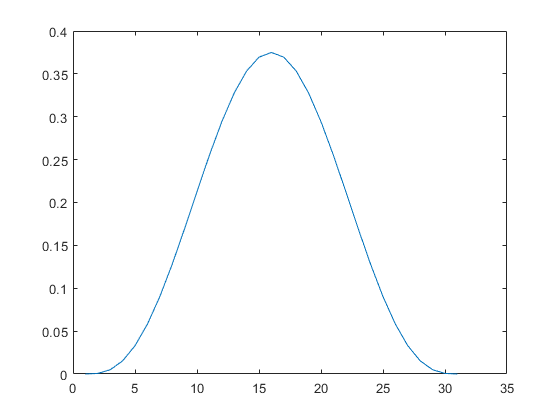

figure();
plot(Q3)

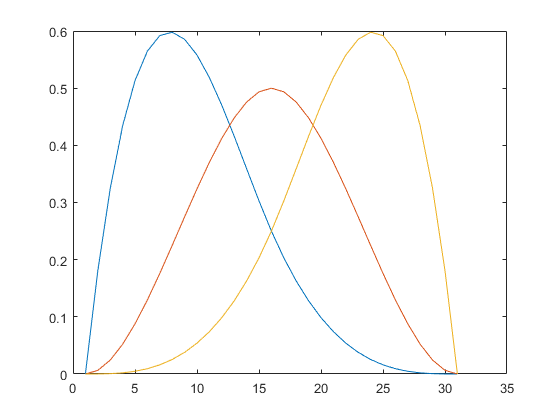

figure();
%Visualize the spline functions
for i = 1:size(Q1, 2)
    plot(Q1(:, i))
    hold on;
end

B2 = spmak(k2, eye(p2));
Q2 = fnval(B2, 1:m(2))';
Q = kron(speye(2), kron(Q1, Q2))

Q =   (33,1)       0.0585
  (34,1)       0.0926
  (35,1)       0.1069
  (36,1)       0.1057
  (37,1)       0.0936
  (38,1)       0.0751
  (39,1)       0.0547
  (40,1)       0.0367
  (41,1)       0.0231
  (42,1)       0.0134
  (43,1)       0.0068
  (44,1)       0.0029
  (45,1)       0.0009
  (46,1)       0.0001
  (64,1)       0.1051
  (65,1)       0.1663
  (66,1)       0.1919
  (67,1)       0.1898
  (68,1)       0.1681
  (69,1)       0.1348
  (70,1)       0.0982
  (71,1)       0.0659
  (72,1)       0.0415
  (73,1)       0.0240
  (74,1)       0.0123
  (75,1)       0.0052
  (76,1)       0.0015
  (77,1)       0.0002
  (95,1)       0.1407
  (96,1)       0.2227
  (97,1)       0.2569
  (98,1)       0.2541
  (99,1)       0.2250
 (100,1)       0.1805
 (101,1)       0.1314
 (102,1)       0.0882
 (103,1)       0.0556
 (104,1)       0.0321
 (105,1)       0.0165
 (106,1)       0.0069
 (107,1)       0.0021
 (108,1)       0.0003
 (126,1)       0.1663
 (127,1)       0.2634
 (128,1)       0.3038
 (129,


[x1, x2] = meshgrid(1:m(2), 1:m(1))

x1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31
     1     2     3     4     5     6     7     8     9    10

x2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     6     6     6     6     6     6     6     6     6     6

size(Q)

ans =         1922          30


y = [x1(:), x2(:)]

y =      1     1
     1     2
     1     3
     1     4
     1     5
     1     6
     1     7
     1     8
     1     9
     1    10
